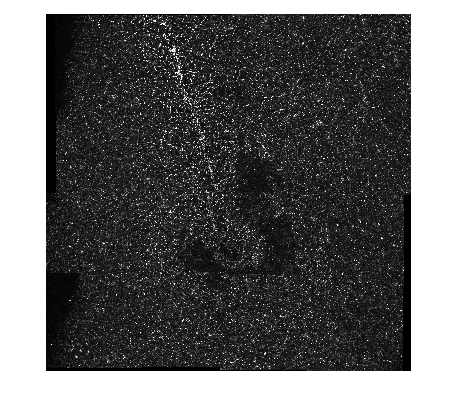

im_confocal_m=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C2-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_m,[]);

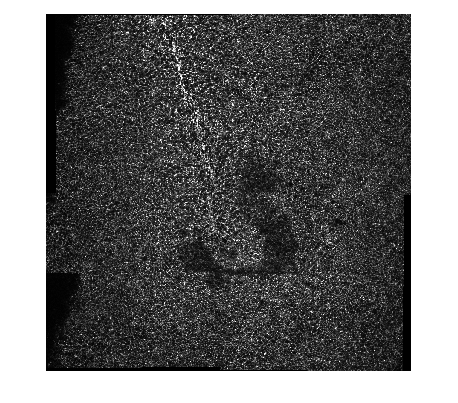

im_confocal_a=read(Tiff('\\lfs.lifesci.dundee.ac.uk\lfs\cjw\Jason\Confocal\im1\C3-MAX_HH4_pMlc2_P584_DAPI_230617a.lif - No2_63X_HN_TileScan_001_Merging001.tif','r'));
imshow(im_confocal_a,[]);


DLSM_pixel=.65 ;%microns
confocal_pixel = 1/5.548 ;
confocal_tile = @(x) round(x*DLSM_pixel/confocal_pixel); %to get 
%equivalent tile size to 180, 256, etc pixel tiles on DLSM images

tile_size_DSLM=32;
tile_size_confocal=confocal_tile(tile_size_DSLM)

tile_size_confocal = 115

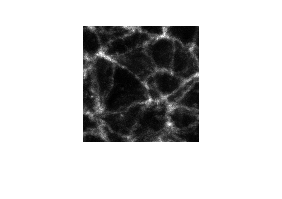

loc1 = [3300,220]; %in upper right uniform area
tile1a = im_confocal_a(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1a,[])

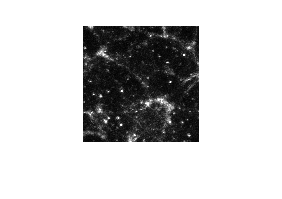

tile1m = im_confocal_m(loc1(2):loc1(2)+tile_size_confocal,loc1(1):loc1(1)+tile_size_confocal);
imshow(tile1m,[])

import utilities.perdecomp;
FT = @(x) abs(fftshift(fft2(perdecomp(x))));

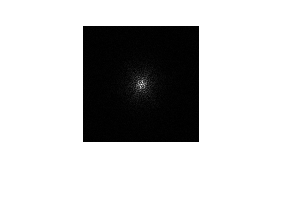

imshow(FT(tile1a),[0,100000])

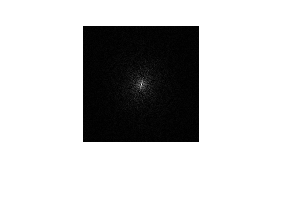

imshow(FT(tile1m),[0,100000])

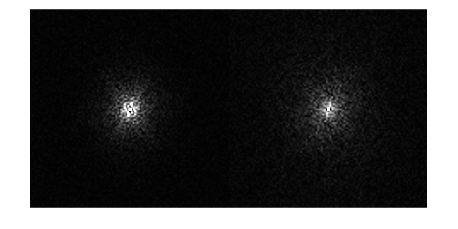

montage({FT(tile1a), FT(tile1m)},[], DisplayRange=[0,50000])

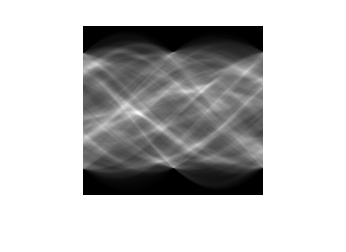

imshow(radon(tile1a),[])

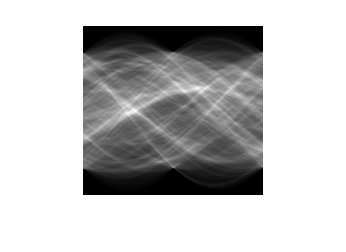

imshow(radon(tile1m),[])

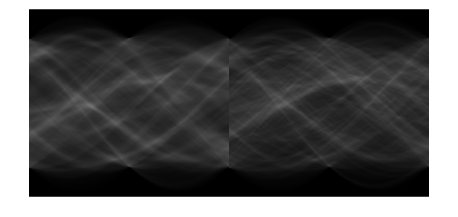

montage({radon(tile1a), radon(tile1m)},[], DisplayRange=[1,25000])
xlabel("angle alpha")
ylabel("position delta")

mask = zeros(size(tile1a))

mask =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0

xlen=size(tile1a,1)

xlen = 116

ylen=size(tile1a,2)

ylen = 116

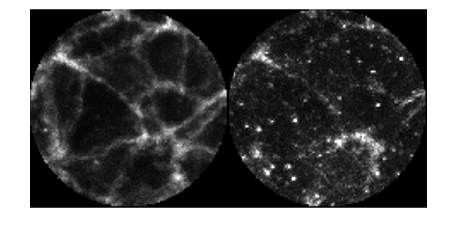

for x=1:xlen
    for y = 1:ylen
        if sqrt((x-xlen/2)^2+(y-ylen/2)^2) < min(size(tile1a))/2
            mask(x,y)=1;
        end
    end
end
circle1a= double(tile1a).*mask;
circle1m= double(tile1m).*mask;
montage({circle1a, circle1m}, [], displayRange=[0,255])

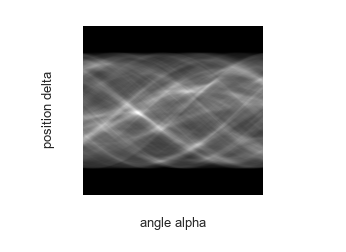

imshow(radon(circle1a),[])
xlabel("angle alpha")
ylabel("position delta")

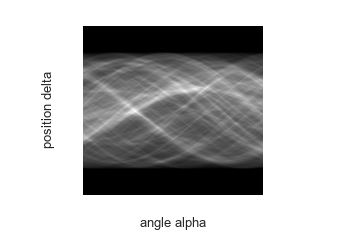

imshow(radon(circle1m),[])
xlabel("angle alpha")
ylabel("position delta")

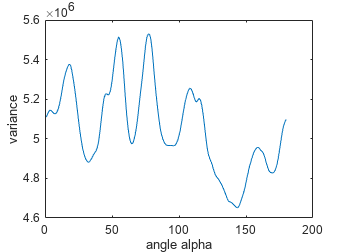

angles1a = radon(circle1a);
var1a = var(angles1a, [], 1);
angles1m = radon(circle1m);
var1m = var(angles1m, [], 1);
plot(var1a)
xlabel("angle alpha")
ylabel("variance")

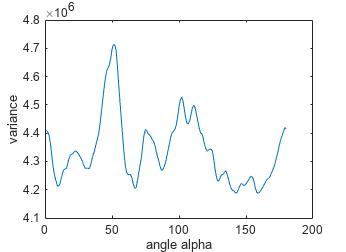

plot(var1m)
xlabel("angle alpha")
ylabel("variance")

[variance, ang]=max(var1a);
xo=xlen/2;
yo=ylen/2;
ang = deg2rad(-ang+90)

ang = 0.2269

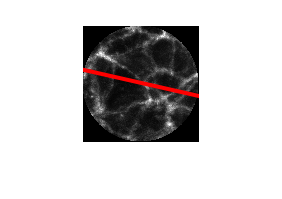

x1 = xo+cos(ang)*100; 
y1 = yo+sin(ang)*100;
x2 = xo-cos(ang)*100;
y2 = yo-sin(ang)*100;
%circle1a_2=imadjust(circle1a);
circle1a_red = insertShape(cast(circle1a, "uint8"), 'line', [x1 y1 x2 y2], 'LineWidth', 5, 'Color', [255,0,0]);
imshow(circle1a_red, [0,255])

[variance, ang]=max(var1m);
xo=xlen/2;
yo=ylen/2;
ang = deg2rad(-ang+90)

ang = 0.6807

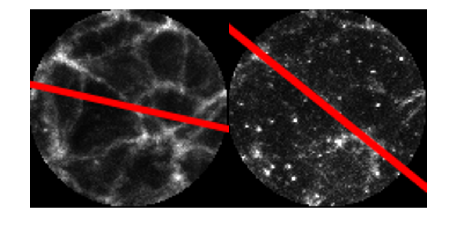

x1 = xo+cos(ang)*100; 
y1 = yo+sin(ang)*100;
x2 = xo-cos(ang)*100;
y2 = yo-sin(ang)*100;
%circle1a_2=imadjust(circle1a);
circle1m_red = insertShape(cast(circle1m, "uint8"), 'line', [x1 y1 x2 y2], 'LineWidth', 5, 'Color', [255,0,0]);
montage({circle1a_red, circle1m_red})

Streichan et al's Radon transform process:

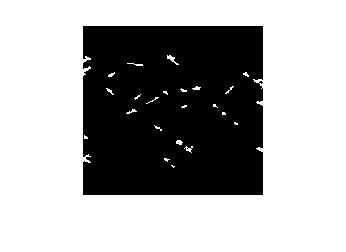

n_lines=10;
%Do the radon transform (sqare image)
r=radon(tile1m);
%find maxima using extended maxima transform
maxima = imextendedmax(r,800);
imshow(maxima,[])

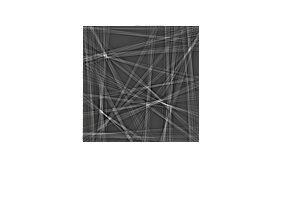

%inverse radon transform to identify maxima-associated regions
%on real space image
maxima_lines = iradon(maxima,0:179);
imshow(maxima_lines,[])

clf
%imshow(tile1m,[])
hold on
%list radon-space coordinates of maxima pixels
sm = sparse(maxima)

sm = 169×180 sparse logical array
  (34,1)      1
  (35,1)      1
  (36,1)      1
  (37,1)      1
  (44,1)      1
  (45,1)      1
  (46,1)      1
  (47,1)      1
  (48,1)      1
  (49,1)      1
  (50,1)      1
 (132,1)      1
 (133,1)      1
 (134,1)      1
 (135,1)      1
 (136,1)      1
  (34,2)      1
  (35,2)      1
  (36,2)      1
  (43,2)      1
  (44,2)      1
  (45,2)      1
  (46,2)      1
  (48,2)      1
  (49,2)      1
 (110,2)      1
 (111,2)      1
 (112,2)      1
 (113,2)      1
 (132,2)      1
 (133,2)      1
 (134,2)      1
 (135,2)      1
  (31,3)      1
  (32,3)      1
  (34,3)      1
  (35,3)      1
  (36,3)      1
  (43,3)      1
  (44,3)      1
  (45,3)      1
  (46,3)      1
  (49,3)      1
 (111,3)      1
 (112,3)      1
 (113,3)      1
 (131,3)      1
 (132,3)      1
 (133,3)      1
 (134,3)      1
 (135,3)      1
 (136,3)      1
  (31,4)      1
  (32,4)      1
  (33,4)      1
  (34,4)      1
  (35,4)      1
  (43,4)      1
  (44,4)      1
  (45,4)      1
 (111,

indices = find(sm)

indices =     34
    35
    36
    37
    44
    45
    46
    47
    48
    49


[nd, ntheta]= size(maxima)

nd = 169

ntheta = 180

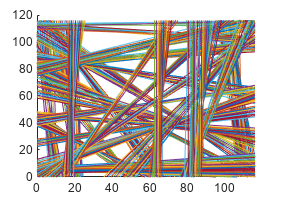

[d,theta] = ind2sub([nd, ntheta],indices);
%for each radon space coordinate, extract profile along that line
for i =1:size(d)
di=d(i)-ceil(nd/2);
thetai=deg2rad(theta(i));
[xs,ys]=lineboxintercepts(di, thetai, -tile_size_confocal/2, -tile_size_confocal/2, tile_size_confocal/2+1, tile_size_confocal/2+1);
xs=xs+tile_size_confocal/2
ys=ys+tile_size_confocal/2
plot(xs,ys)
profile=improfile(tile1m, xs+tile_size_confocal/2, ys+tile_size_confocal/2);
%use the extended H maxima function on profiles
end
hold off

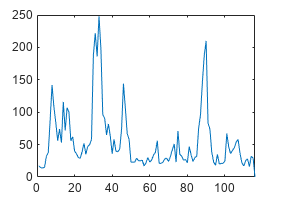

plot(profile)

[xs,ys]=lineboxintercepts(3, deg2rad(45), 0, 0, tile_size_confocal+1, tile_size_confocal+1)

xs =          0    4.2426


ys =     4.2426         0


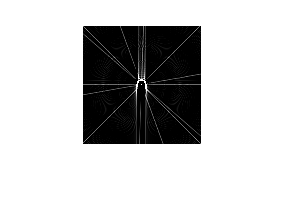

m=zeros(nd,ntheta);


m(89,:)=100;

m(85,46)=100;
m(85,91)=100;
m(85,136)=100;
m(85,179)=100;
m(85,50)=100;
m(85,21)=100;
m(85,101)=100;

imshow(iradon(m, 0:179))

function [xs,ys]=lineboxintercepts(d, theta, bx1, by1, bx2,by2)
%a vertical line at x=bx1=0
yintercept = d*(cos(theta)^2/sin(theta) +sin(theta));
%a vertical line at x=bx2
rightborderintercept=yintercept-bx2*cos(theta)/sin(theta);
leftborderintercept = yintercept-bx1*cos(theta)/sin(theta);
%a horizontal line at y=by1=0
xintercept = d*(sin(theta)^2/cos(theta)+cos(theta));
%a horizontal line at y=by2
topborderintercept = xintercept - by2*sin(theta)/cos(theta);
bottomborderintercept = xintercept - by1*sin(theta)/cos(theta);
xs = [bx1, topborderintercept, bottomborderintercept, bx2];
ys = [leftborderintercept, by2, by1, rightborderintercept];
filter = xs >=bx1 & xs <=bx2 & ys>=by1 & ys<=by2;
xs=xs(filter);
ys=ys(filter);
end